# **Task_02b:**   Extract the Modal parameters from the Impact Test data

Recall the parametric equation of a Frequency Response Function (FRF) of a Mechanical structure:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$$
          

where we have:

- **MODAL poles**:       $\lambda_k \;\;\;=\;-\zeta_k \ldotp \omega_{n_k } \;\;\;+\;\;\;j\ldotp \omega_{n_k } \ldotp \sqrt{\;1\;-{\zeta_k }^2 \;}$

- **RESIDUES**:            $R_k$

 See the following Appendix for a reminder on where this parametric cam from

-   [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

So for our single floor tower, we need to:

- Load the timeseries data from our Impact test simulation

- Convert the timeseries data into a Frequency Response Function (FRF)

- Extract the MODAL properties from the FRF

- we'll save these results to the file `bh_SYS_ID_RESULTS.mat`

Our **Modal Fitting** process can be summarized by the following workflow pipeline:

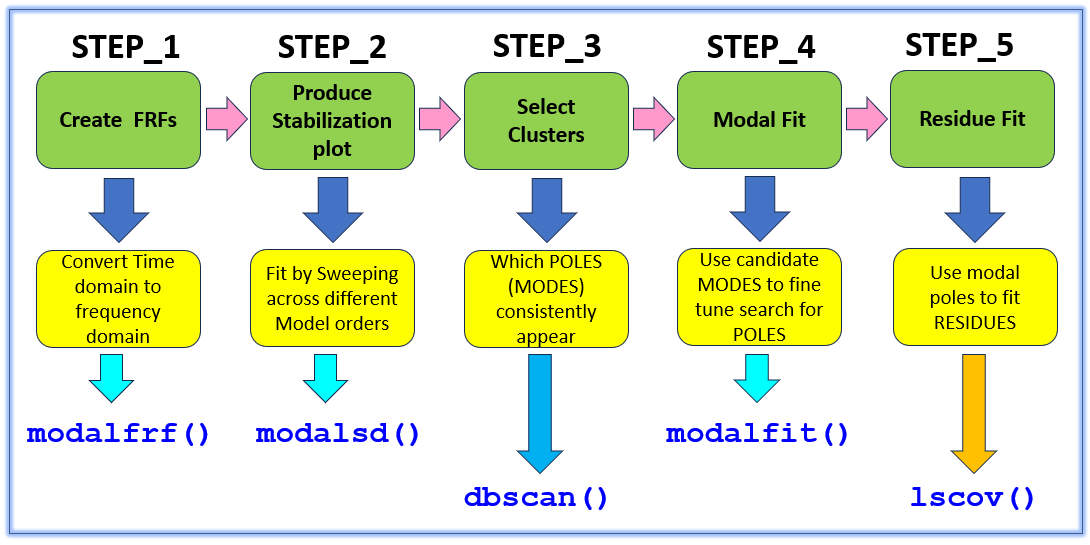

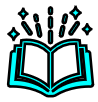 You can read-up on the DOC for the 5 main functions that we'll be utilizing here:

- **Signal Processing Toolbox**

- [`modalfrf()`](matlab:  doc modalfrf)` , `[`modalsd()`](matlab:  doc modalsd)` , `[`modalfit()`](matlab:  doc modalfit)

- **Statistics and Machine Learning Toolbox**

- [`dbscan()`](matlab: doc dbscan)

- **MATLAB**

- [`lscov()`](matlab: doc lscov) 

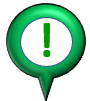We'll also use some "hand rolled" code, eg:

- We'll use a custom **Value Class** defined in the file  [`CLS_sdyn_frf.m`](matlab:  edit  bh_Modal.CLS_sdyn_frf) to visualize the fitted FRF

`Bradley Horton:  bhorton@mathworks.com`

# Load in the Time Series measurement data

Clear your Workspace

clear

**NOTE:**  For this structure and for the excitation profile that we have applied ... a 1-element response produces almost identical results as a 5-element model.

MEAS_tab   = readtable("bh_IMPACT_TEST.xlsx");
%MEAS_tab   = readtable("bh_IMPACT_TEST_5_ele_per_column.xlsx");

So what are the raw column names

MEAS_tab.Properties.VariableNames'

ans = 3×1 cell array
    {'time'}
    {'F1'  }
    {'X1'  }


Rename the COLUMNS

MEAS_tab.Properties.VariableNames = ["t","F1", "X1"];

So how big is our MEASUREMENT data

whos MEAS_tab

  Name              Size             Bytes  Class    Attributes

  MEAS_tab      20001x3             481489  table              



Plot the measured **timeseries data**

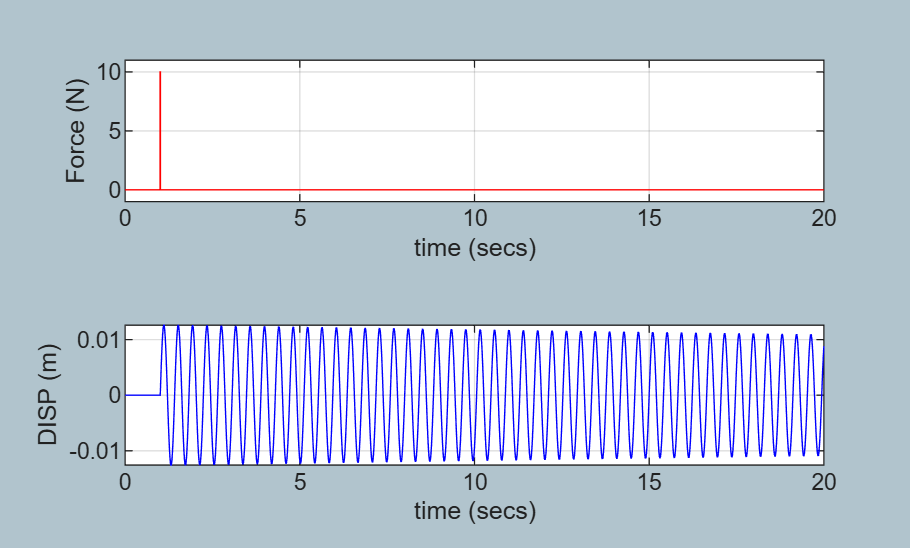

figure
tiledlayout(2,1)
nexttile
    stairs(MEAS_tab.t, MEAS_tab.F1, "-r"); 
        xlabel("time (secs)"); ylabel("Force (N)"); grid on
        ylim([-1, 1.1*max(MEAS_tab.F1)])

nexttile
    stairs(MEAS_tab.t, MEAS_tab.X1, "-b"); 
       xlabel("time (secs)"); ylabel("DISP (m)"); grid on

# Configure some signal processing parameters

### Define Fs

Define the sampling frequency 

Fs_hz     = 1/(MEAS_tab.t(2) - MEAS_tab.t(1))

Fs_hz = 1000

### Define U and Y

Define the input(FORCE) and response(DISPLACEMENTS) data

in_col    = MEAS_tab.F1;
out_col   = MEAS_tab.X1;

### Define window attributes

For an impact test we typically apply an **exponential window to the RESPONSE** channels and "**no" window to the EXCITATION** channel.  We can accomplish BOTH by defining the UNIFORM window to be unity during the impact duration and then exponentially decaying after the application of the impact force,

- see the function [`bh_create_expon_window()`](matlab:  open  bh_create_expon_window)

% THE_WINDOW =  ones( length(MEAS_tab.t), 1 );
% n_OVERLAP  = 0;
%-----------------------------------------------------------
[THE_WINDOW, TAU_window] = bh_create_expon_window(MEAS_tab.t, F_col=in_col);
%[THE_WINDOW, TAU_window] = bh_create_expon_window(MEAS_tab.t);
n_OVERLAP  = 0;

Plot what the timeseries data looks like when the window gets applied

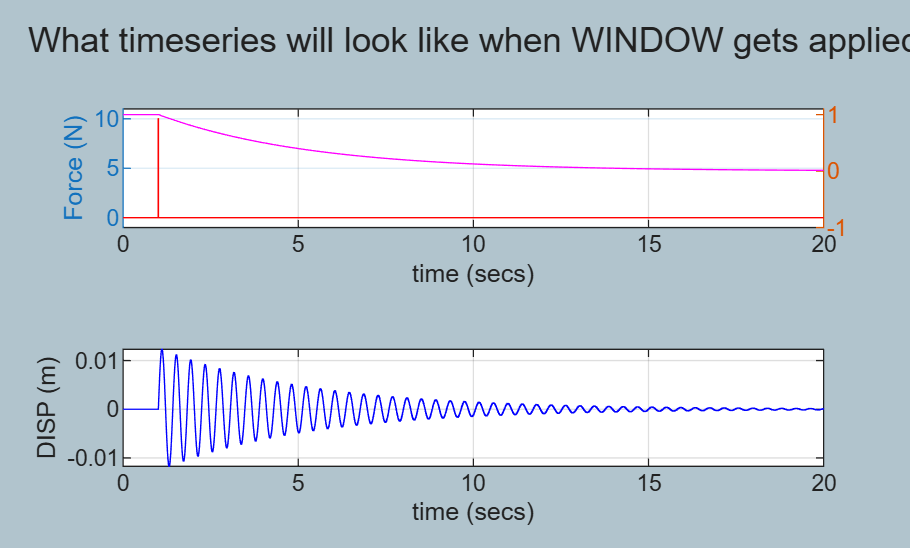

figure
    tiledlayout(2,1)    
        nexttile
           yyaxis left
            stairs(MEAS_tab.t, THE_WINDOW.*MEAS_tab.F1, "-r"); 
                xlabel("time (secs)"); ylabel("Force (N)"); grid on
                ylim([-1, 1.1*max(MEAS_tab.F1)])    
           yyaxis right
            plot(MEAS_tab.t, THE_WINDOW, "-m");            
            ylim([-1, 1.1]) 
        nexttile
            stairs(MEAS_tab.t, THE_WINDOW.*MEAS_tab.X1, "-b"); 
                xlabel("time (secs)"); ylabel("DISP (m)"); grid on
                sgtitle("What timeseries will look like when WINDOW gets applied")

# **STEP_1:**    Estimate the Systems FRF

 **DOC**:   see [`modalfrf()`](https://au.mathworks.com/help/releases/R2024b/signal/ref/modalfrf.html)  - NOTE we're stating that the RESPONSE sensor type is **DISPLACEMENT**

[all_frf, all_f] = modalfrf( in_col, out_col, Fs_hz, ...
                             THE_WINDOW, n_OVERLAP, Sensor="dis");

whos  all_frf  all_f

  Name             Size             Bytes  Class     Attributes

  all_f        10001x1              80008  double              
  all_frf      10001x1             160016  double    complex   



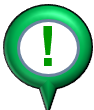 **NOTE:**  the frequency vector `all_f` (in Hz) that is returned only includes frequencies up to the NYQUIST frequency

all_f(end)

ans = 499.9750

## **Visualize the estimated FRFs**

meas.frf       = all_frf;
meas.f_hz      = all_f; 
meas.w         = 2*pi*meas.f_hz;
meas.frf_dB    = 20*log10(abs(meas.frf));
meas.phase_deg = rad2deg(  angle(meas.frf)   );

## Specify the Frequency range of interest and PLOT

roi.range_Hz = [0, 10];

tmp_ind      = find( (meas.f_hz > roi.range_Hz(1)) & (meas.f_hz < roi.range_Hz(2))  );

roi.f_Hz     = meas.f_hz(tmp_ind);
roi.frf      = meas.frf(tmp_ind, :);

And plot the ROI too

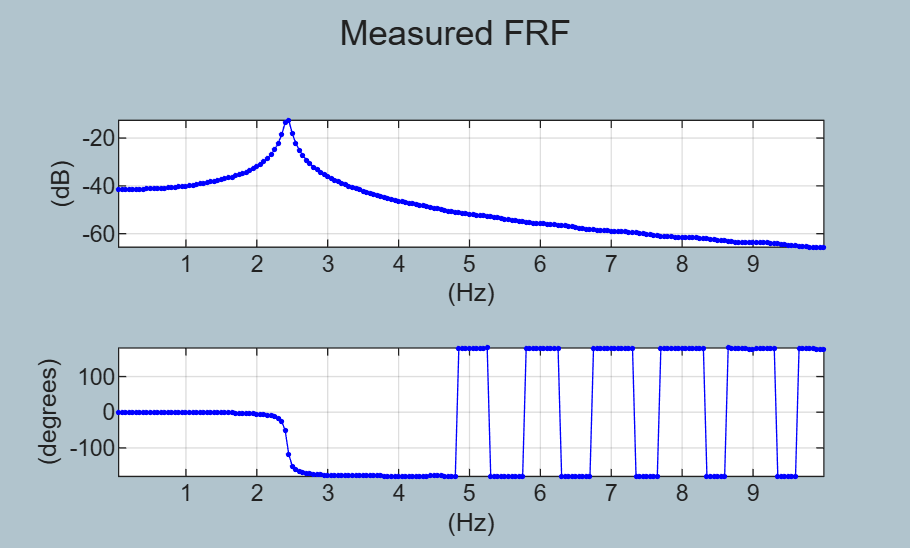

figure;
      hax(1) = subplot(2,1,1); 
           plot(roi.f_Hz, 20*log10( abs(roi.frf)), "-b.", "DisplayName","MEAS")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(dB)");

      hax(2) = subplot(2,1,2); 
           plot(roi.f_Hz, rad2deg( angle(roi.frf) ), "-b.")
               grid on; axis tight
               xlabel("(Hz)");  ylabel("(degrees)")

      sgtitle("Measured FRF")         

# **STEP_2:**    Produce Stabilization plot

try_it_FitMethod = "lsce";

### Consider the Stabilization diagram

 **DOC**:   see  [`modalsd()`](https://au.mathworks.com/help/releases/R2024b/signal/ref/modalsd.html)

We'll use ALL of our FRF channels

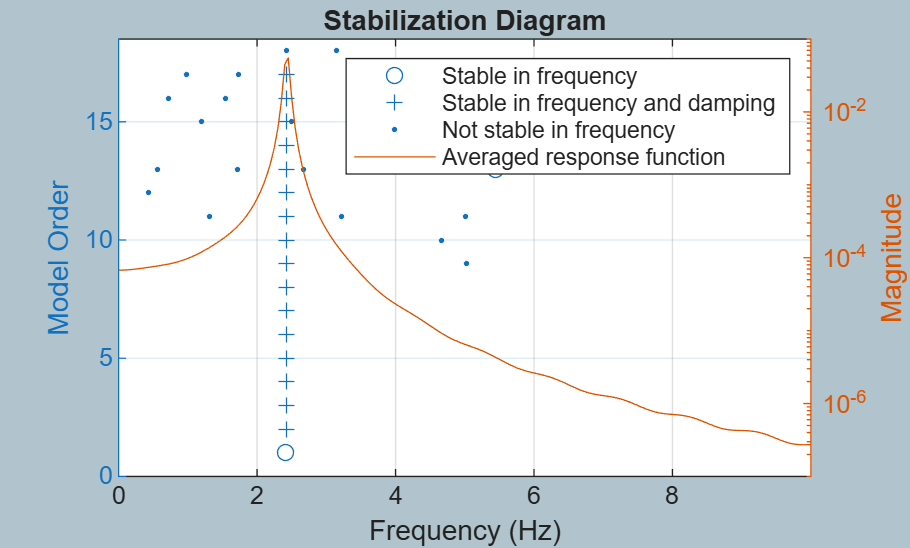

fn_sd =     2.4142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.4298       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.4298       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.4298       NaN       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.4298       NaN       NaN       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.4298       NaN       NaN       NaN       NaN       NaN         0         0       

MAXMODES = 20;

figure   %  the STABILIZATION plot
    fn_sd = modalsd( meas.frf, meas.f_hz, Fs_hz, ...
                     MaxModes=MAXMODES, ...
                     FreqRange=roi.range_Hz, ...
                     FitMethod=try_it_FitMethod)

Maybe we weren't able to sweep across the desired MAX modes

ACTUAL_MAXMODES = size(fn_sd, 2);  

remove NaNs and ZEROS

FN_HZ_ALL =   rmmissing(fn_sd(:));
tmp_ind   =  FN_HZ_ALL == 0;
FN_HZ_ALL(tmp_ind) = [];

# **STEP_3:**   Look for Clusters from the Stabilization plot

### Explore the distribution of the identified modes

 REMEMBER: many of the modes will NOT be real modes, rather they will be computational ones that we need to ignore. 

### Select modes based on CLUSTERING and a count threshold

 So let's utilize a data **CLUSTERING** algorithm to semi automate where we think the real modes are.  We will need to tune this, e.g.:  

- the **neighborhood radius** may need some "trial/error" tuning.

- the **minimum number of counts** within a cluster may need some "trial/error" tuning.

See:  [`bh_collect_by_clustering()`](matlab:  open bh_collect_by_clustering)` - uses` [`dbscan()`](matlab: doc dbscan) to cluster candidate physical modes

Found 1 candidate modes:
 Mode  1: f = 2.4298 Hz  (count = 17)


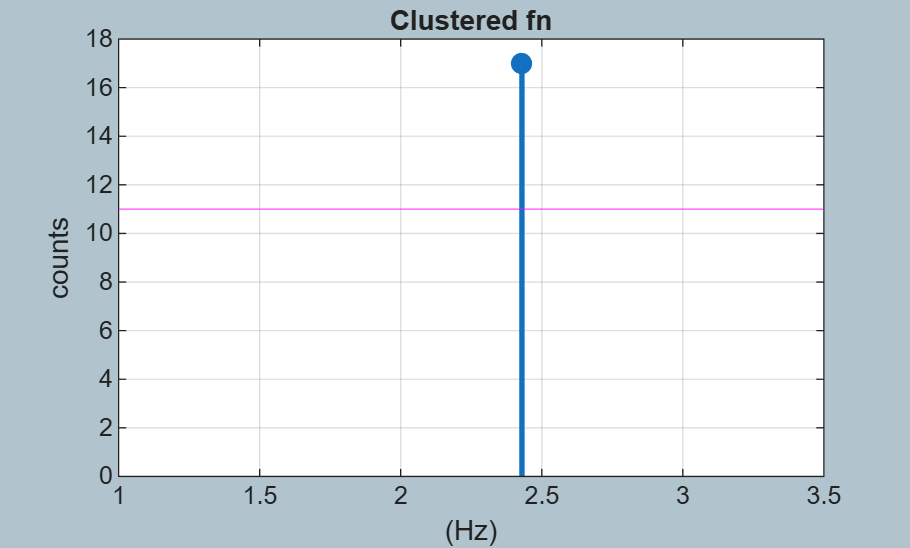

clust_fHz_radius = 1;
clust_min_counts = floor(0.66*ACTUAL_MAXMODES);
clust_fHz_range  = roi.range_Hz;

my_fhz_list_FROM_collect = bh_collect_by_clustering(FN_HZ_ALL, clust_fHz_radius, clust_min_counts, fHz_range=clust_fHz_range);

So our candidate resonant frequencies are:

my_fhz_list_FROM_collect

my_fhz_list_FROM_collect = 2.4298

# **STEP_4:**   Extract our Modal Poles

So from the stabilization diagram, how many modes do you think we should try and fit ?

NUM_MODES_TO_FIT = 6

NUM_MODES_TO_FIT = 6

Now do a MODAL fit:

- see DOC for [`modalfit()`](https://au.mathworks.com/help/releases/R2024b/signal/ref/modalfit.html)

- 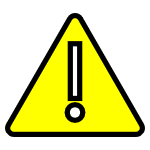 **NOTE:**  We'll specify the frequencies extracted from our histogram and pass these into [`modalfit()`](https://au.mathworks.com/help/releases/R2024b/signal/ref/modalfit.html) as 'PhysFreq'.  We'll also specify a HIGHER target number of modes to fit ... to see if there's anything else there. Overspecifying the number of modes gives better (?) results.

[fn,dr,ms] = modalfit( meas.frf, meas.f_hz, Fs_hz, ...
                       NUM_MODES_TO_FIT, ...
                       PhysFreq=my_fhz_list_FROM_collect, ...
                       FreqRange=roi.range_Hz, ...
                       FitMethod=try_it_FitMethod);

Remove any Nans:

tmp_ind  = ~isnan(fn) & ~isnan(dr);

fn_clean = fn(tmp_ind);
dr_clean = dr(tmp_ind);
wn_clean = 2*pi*fn_clean;

Tabulate these

results_table = array2table([wn_clean, fn_clean(:), dr_clean(:)],'VariableNames',{'wn','fn_hz','zeta'})

results_table = 1×3 table
      wn      fn_hz       zeta  
    ______    ______    ________

    15.267    2.4298    0.015604

	Get insights using Copilot


### Save the results to a MAT file:

 Save the Undamped Natural frequencies to a MAT file

wn_radpersec_original_building = wn_clean;

save bh_SYS_ID_RESULTS wn_radpersec_original_building

# **STEP_5:**   Extract our Modal RESIDUES

Now let's compute residues.  Recall that our FRF has the parametric form

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


For some background information on the MODAL model see the following companion document:

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

So we now need to compute the residues for every mode in the FRF

- see [`bh_Modal.bh_calc_resids_LIVE()`](matlab:  open  bh_Modal.bh_calc_resids_LIVE) - a weighted Least Squares formulation using  [`lscov()`](matlab: doc lscov) 

[my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                    dr_clean, ...
                                                    roi.f_Hz, ...
                                                    roi.frf    );

Visually confirm Residues have phases close to  -90 degrees

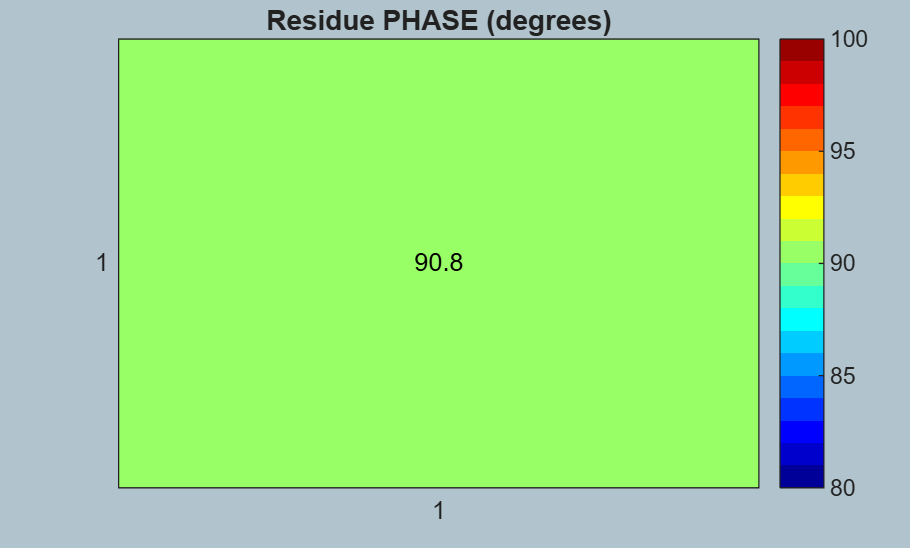

tmp_res_phas_degs = abs( rad2deg(angle(my_R)) );

figure;
    heatmap(tmp_res_phas_degs, "Colormap", jet(20) );
        title("Residue PHASE (degrees)")
        clim([80 100])

# Compare Measured FRF against Fitted FRF

## So what does the curve fit look like ?

We've completed the curve fit.  So let's combine our identified terms into a final model:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


We'll use a custom **Value Class** defined in the file  [`CLS_sdyn_frf.m`](matlab:  edit  bh_Modal.CLS_sdyn_frf) to represent the FRF

- `CLS_sdyn_frf(the_damping_zeta, ``the_wn_rads``, the_R, the_E, the_F)`

[my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                    dr_clean, ...
                                                    roi.f_Hz, ...
                                                    roi.frf   );

my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf( results_table.zeta,  ...
                                     results_table.wn,   ...
                                     my_R, my_e, my_f);

my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;

%Echo a summary of our model:
my_sdyn_OBJ.print()


---------------------------------------------------------------------------
 ID_label = sdt_foo

 mode#      Wn[Hz]       DAMP[-]       Real(R)          Imag(R)        Phase(R)[degs]      
  1          2.430      0.01560      -0.000880668       -0.0632441     -90.80  

 E = 3.97652e-06 + i*-2.43563e-05
 F = 7.79913e-06 + i*-7.10951e-07

Plotting:  Part 1 - Plot the model against the Measurement data

figure;

tiledlayout(2,1)

hax(1) = nexttile;
   plot(roi.f_Hz, 20*log10(abs(roi.frf)), "-r", "LineWidth",3,"DisplayName","MEAS")
       grid on; axis tight
       xlabel("(Hz)");   ylabel("(dB)");
       
hax(2) = nexttile;
   plot(roi.f_Hz, rad2deg(angle(roi.frf)), "-r", "LineWidth",3)
       grid on; axis tight
       xlabel("(Hz)");  ylabel("(degrees)")

Now superimpose on these plots the Fitted Model FRF

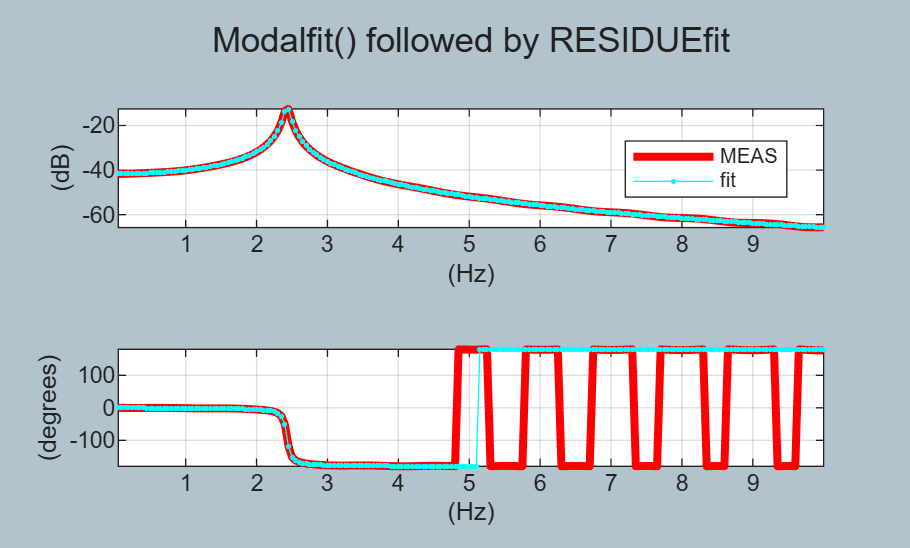

hold(hax(1),"on")
    axes(hax(1))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-c.","DisplayName","fit");

hold(hax(2),"on")
    axes(hax(2))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-c.");

legend(hax(1), "Location", "best")

linkaxes(hax, "x")
sgtitle("Modalfit() followed by RESIDUEfit")

 Plotting:  Part 2 - Plot the model FRF in 3D

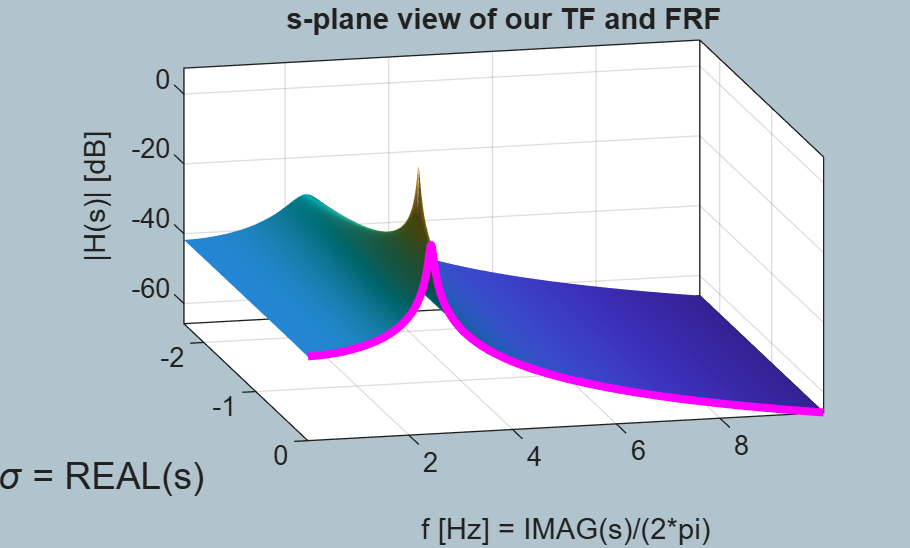

  my_sdyn_OBJ.plot_3d_db()